2.a. Recall that transformation matrices can be used to rotate, scale, and/or skew vectors. For example, the rotation matrix

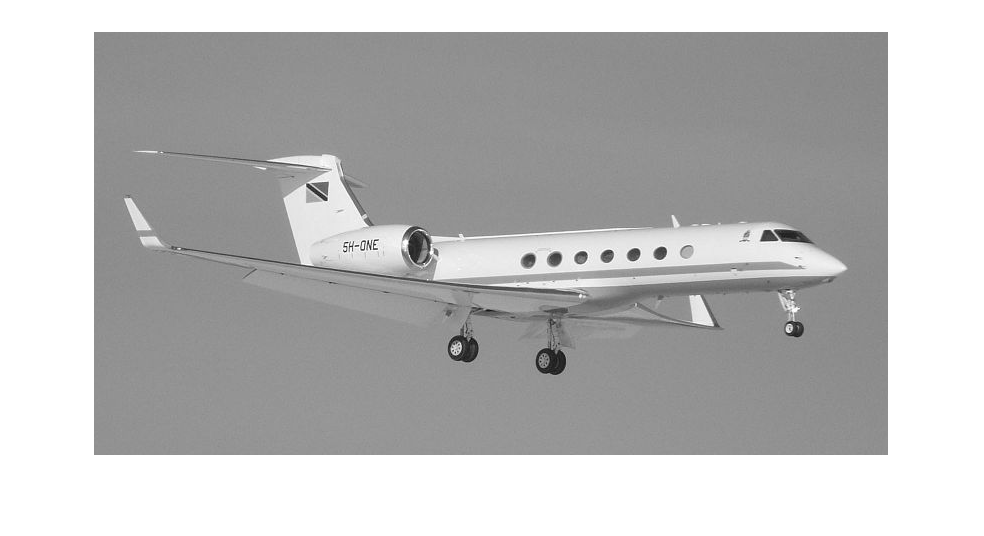

img = rgb2gray(imread('gulfstream.png'));
imshow(uint8(img))

A = [sqrt(2)/2 -sqrt(2)/2; sqrt(2)/2 sqrt(2)/2]

A =     0.7071   -0.7071
    0.7071    0.7071


will rotate a vector 45 degrees counterclockwise (CCW). Points may be thought of as vectors from the origin, so we could equivalently say that it will rotate a point by 45 degrees CCW about the origin. For a vector 

X =[x0,y0] please describe (in words) the effect of the transformation

X1 = AAX0

In other words, how does 𝑋1 relate to 𝑋0? Hint: when considering a series of matrix transformations, it is best to think of them as being applied one after the other, moving from right to left. 

Answer:

Based on the information in question, when we first apply A transformation on vector X0, it will be rotated 45 degrees counterclockwise. A is actually the following matrix:

theta = pi/4;
A = [cos(theta) -sin(theta); sin(theta) cos(theta)]

A =     0.7071   -0.7071
    0.7071    0.7071


which is a counter-clockwise rotation about the origin.

if we have A*A:

Transform = A*A 

Transform =     0.0000   -1.0000
    1.0000    0.0000


2.C

img = rgb2gray(imread('gulfstream.png'));

%The matrix "A" from part a) is provided for convenience:
theta = pi/4;
A = [cos(theta) -sin(theta); sin(theta) cos(theta)];

%Replace the identity matrix below with your transformation
%matrix, and run this script.
%%%%%%%%%%%% Your code here %%%%%%%%%%%%%%
T = [sqrt(2)/2 -sqrt(2)/4;sqrt(2)/2 sqrt(2)/4];

%%%%%%%%%%%% end of your code %%%%%%%%%%%%%%

%The code below applies the transformation to every pixel in the image, and 
%displays both images. This code takes care of some MATLAB-specific things 
%that have low educational value, and you don't need to understand it.

%adds the translation part to get a complete affine transformation matrix
TWithTranslation = [T [0;0];0 0 1];

%MATLAB affine-transform convention is the transpose of ours, so we feed it
%the transpose of the transformation matrix
tform = maketform('projective',TWithTranslation');
%Images are drawn with the +y axis pointing down. So flip the image before
%and after the transformation to simulate normal Cartesian coordinates
transformed = flipud(imtransform(flipud(img), tform, 'FillValues',255));
imshow(img)

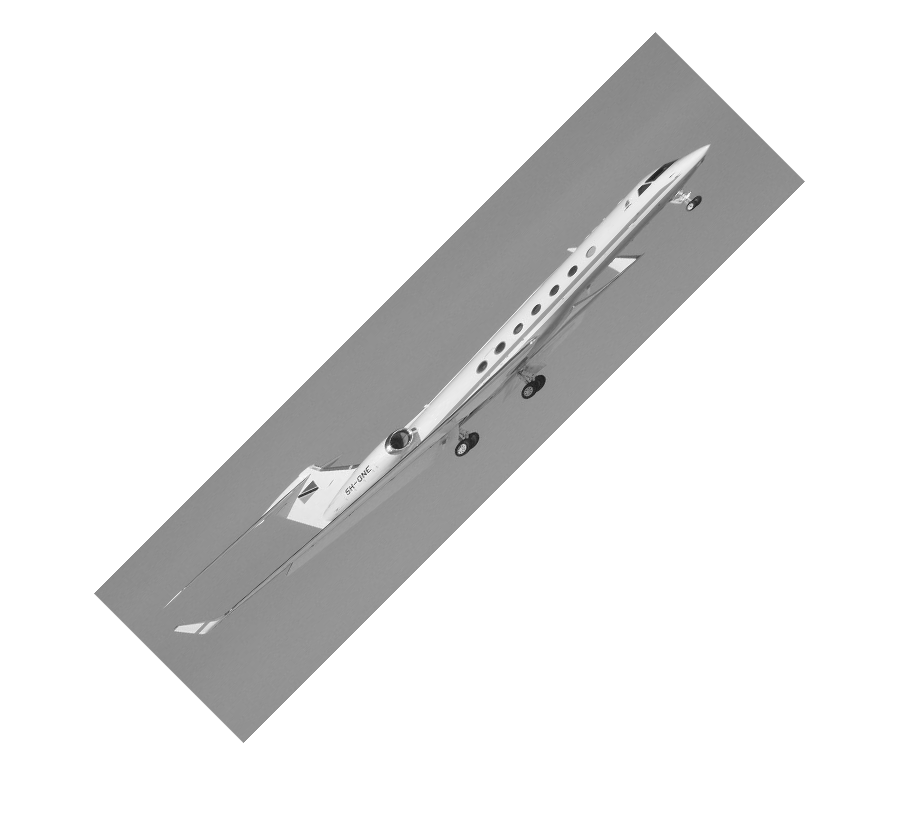

figure
imshow(uint8(transformed))

Transform = [0 -1; 1 0] which is a reflection about origin. Firstly, AA rotate X0 by 45 degrees CCW, then another rotation is exerted 45 degrees which makes it 90 degrees at the end. This is equal to rotating about origin.

2.d   

We will use 2D homogeneous coordinates [𝑥; 𝑦; 1] 𝑇 in this problem. Build a transformation matrix 𝑇 to translate a vector by +2 in the 𝑥 direction (and not perform any rotation). Also build a rotation matrix 𝑅 to rotate a vector 90 degrees CCW. Include 𝑇 and 𝑅 in your report. Given the 2D homogeneous vector. 

p0 =[7;0;1]

use MATLAB to apply the transformation 𝑝1 = 𝑇𝑅𝑝0 and 𝑝2 = 𝑅𝑇𝑝0. Give the values of 𝑝1 and 𝑝2 and explain why they differ from each other.

Answer:

Using 2D homogeneous coordinates, we can define transformation matrix T as follows:

T = [1 0 0 ;0 1 0;0 0 1]

T =      1     0     0
     0     1     0
     0     0     1


p0 =[7;0;1]

p0 =      7
     0
     1


transformed = T*p0

transformed =      7
     0
     1


Based on MATLAB help, for 2-D affine transformations, the last column must contain [0 0 1] homogeneous coordinates

We will define the rotation matrix as bellow:

etha = pi/2

etha = 1.5708

R =  [cos(etha) sin(etha) 0; -sin(etha) cos(etha) 0 ; 0 0 1]

R =     0.0000    1.0000         0
   -1.0000    0.0000         0
         0         0    1.0000


p1 = T*R*p0

p1 =     0.0000
   -7.0000
    1.0000


p2 = R*T*p0

p2 =     0.0000
   -7.0000
    1.0000


As it was expected values in p1 and p2 are different. for p1 firs